# Qbot2 Ground Truth Motion Generation

David Olson, 28 Jan 2021

There are many possibilities for simulating the motion of the Qbot 2.  Ideally, we want to be able to dictate any motion that we are interested in, but which also ensure that the motion dictated is possible.  With these constraints in mind, the standard approach is to develop a dynamic model of the Qbot 2.  This quickly becomes a deep rabbit hole in which the time invested into building this model doesn't provide the appropiate return.  

Instead of building a full dynamic model of the robot, let's use a simpler kinematic model instead.  Typically, kinematic models do not account for the limits of a system's possibiliites.  For example, we know our Qbot 2 can not travel at 60 mph down the highway.  A dynamic model would inherently model this fact, but a kinematic model would not.  A kinematic model will accept and propagate whatever inputs are provided, regardless of reality.  But given the simple kinematic constraints of the Qbot 2, we can build a simple kinematic model that captures the speed limitation (${v^{b\;} }_{\max } =0\ldotp 7\;\frac{m}{s}$).  

The model desribed below focuses on the motion of the left wheel of the Qbot 2.  By descrbing the motion of the left wheel                               ($r_{l\;} \left(t\right),\;v_{l\;} \left(t\right),a_l \left(t\right)$), we also capture the motion of the body frame with respect to the body.  Once we consider the angular motion of the Qbot 2, having parameterized the motion of the left wheel simplifies this task as well.  

### Acceleration Curve

Suppose we want to tell our Qbot 2 to move 3 meters forward.  Simple task, right?  While this may seem simple at first, there are more design choices to make than one would expect.  What does that motion look like?  Is it linear, parabolic, or maybe something else?  Keep in mind, whichever curve we choose for position, we will want to be able to differentiate into velocity and then acceleration.  With that in mind, let's develop a sinusoidal model of motion for the Qbot 2.  


$$a_l \left(t\right)=a\;\mathrm{sin}\left(\frac{\pi \;}{t_{\mathrm{travel}} }t\right),\;\;0<t<t_{\mathrm{travel}}$$


% % Example Computation
% 
% % Select Values for a and t1, t2, and t3
% a = 1.5;
% t1 = 0.3; 
% t2 = 0.9;
% t3 = t1 + t2;
% 
% % Build Acceleration Cuve
% dt = 1e-3;
% t = 0 : dt : t1;
% a_l = [a*sin((pi/t1)*t), zeros(1, length(dt:dt:t2-dt)), -a*sin((pi/t1)*t)];
% 
% % Integrate to Velocity and Position
% t_k = zeros(1, length(a_l));
% v_l = zeros(1, length(a_l));
% r_l = zeros(1, length(a_l));
% 
% for k = 2 : length(a_l)
%     t_k(k) = dt * (k - 1);
%     v_l(k) = a_l(k)*dt + v_l(k-1);
%     r_l(k) = v_l(k)*dt + r_l(k-1);
% end
% 
% % Plot Resulting Curve
% figure
% subplot(3, 1, 1)
% hold on
% plot(t_k, r_l)
% title('Example Position Curve r_l(t)')
% xlabel('Time (s)')
% ylabel('Qbot 2 Left Wheel Position (m)')
% grid on
% subplot(3, 1, 2)
% hold on
% plot(t_k, v_l)
% title('Example Velocity Curve v_l(t)')
% xlabel('Time (s)')
% ylabel('Qbot 2 Left Wheel Velocity (m/s)')
% grid on
% subplot(3, 1, 3)
% hold on
% plot(t_k, a_l)
% title('Example Acceleration Curve a_l(t)')
% xlabel('Time (s)')
% ylabel('Qbot 2 Left Wheel Acceleration (m/s^2)')
% grid on

### Tesing Linear Motion Generation

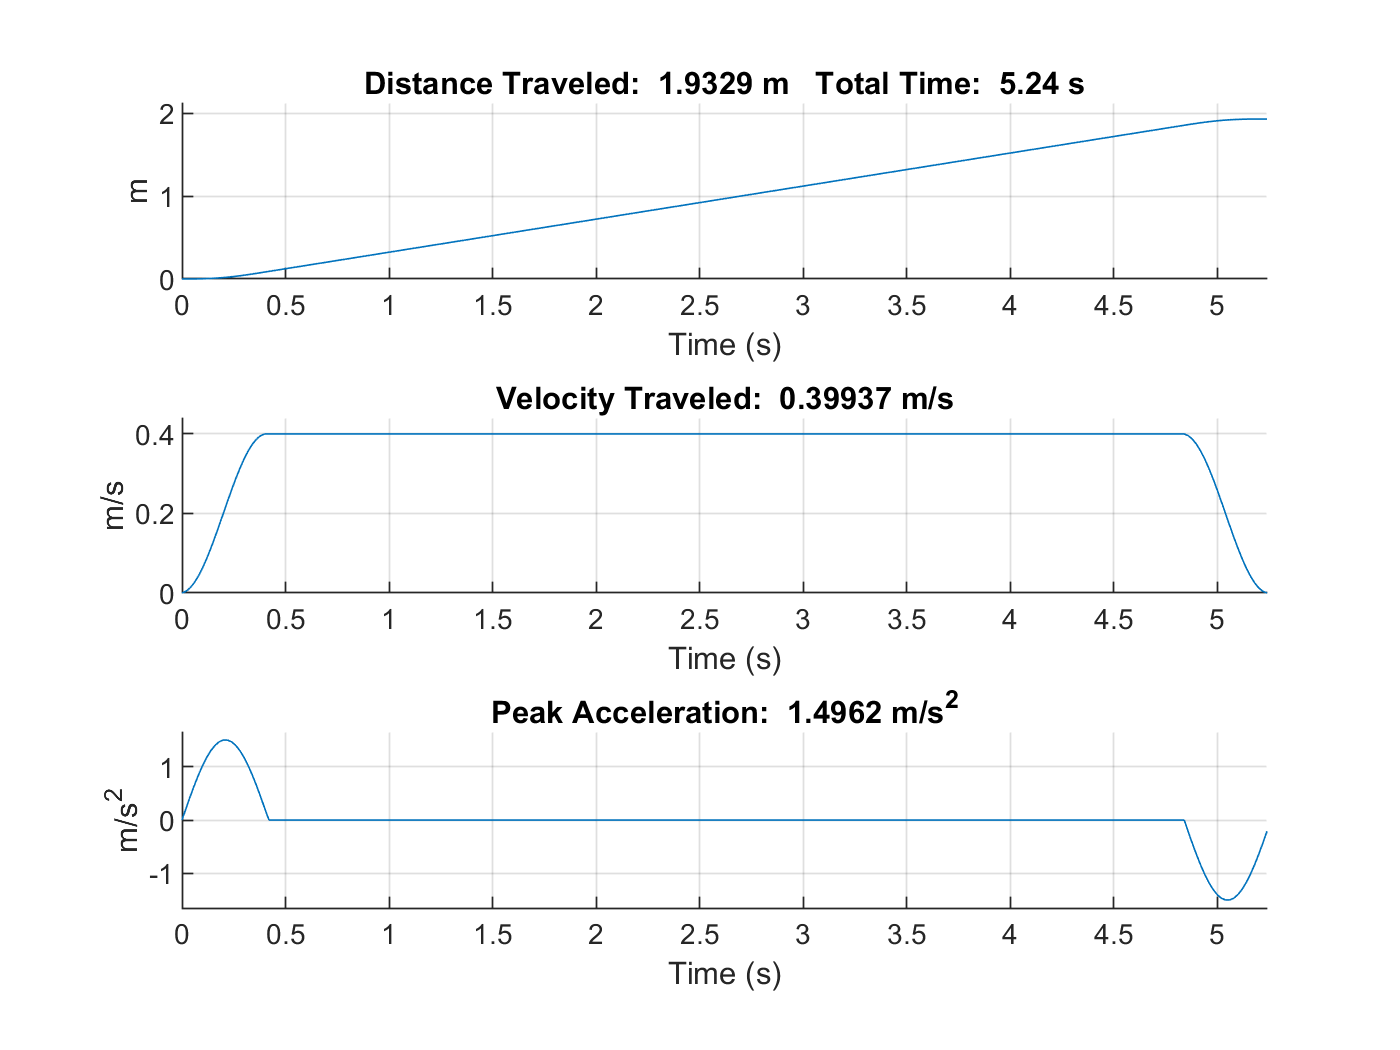

r_des = 1.95;

[t_k, r_l, v_l, a_l] = qbot2_linear_motion_gen(r_des, 1/50);

% Plot Resulting Curve
figure
subplot(3, 1, 1)
hold on
plot(t_k, r_l)
title(['Distance Traveled:  ', num2str(r_l(end)), ' m   Total Time:  ', num2str(t_k(end)), ' s'])
xlabel('Time (s)')
ylabel('m')
xlim([0 t_k(end)])
ylim([0 1.1*r_l(end)])
grid on
subplot(3, 1, 2)
hold on
plot(t_k, v_l)
title(['Velocity Traveled:  ', num2str(max(v_l)), ' m/s'])
xlabel('Time (s)')
ylabel('m/s')
xlim([0 t_k(end)])
ylim([0 1.1*max(v_l)])
grid on
subplot(3, 1, 3)
hold on
plot(t_k, a_l)
title(['Peak Acceleration:  ', num2str(max(a_l)), ' m/s^2'])
xlabel('Time (s)')
ylabel('m/s^2')
xlim([0 t_k(end)])
ylim([-1.1*max(a_l) 1.1*max(a_l)])
grid on

### Testing Angular Motion Generation

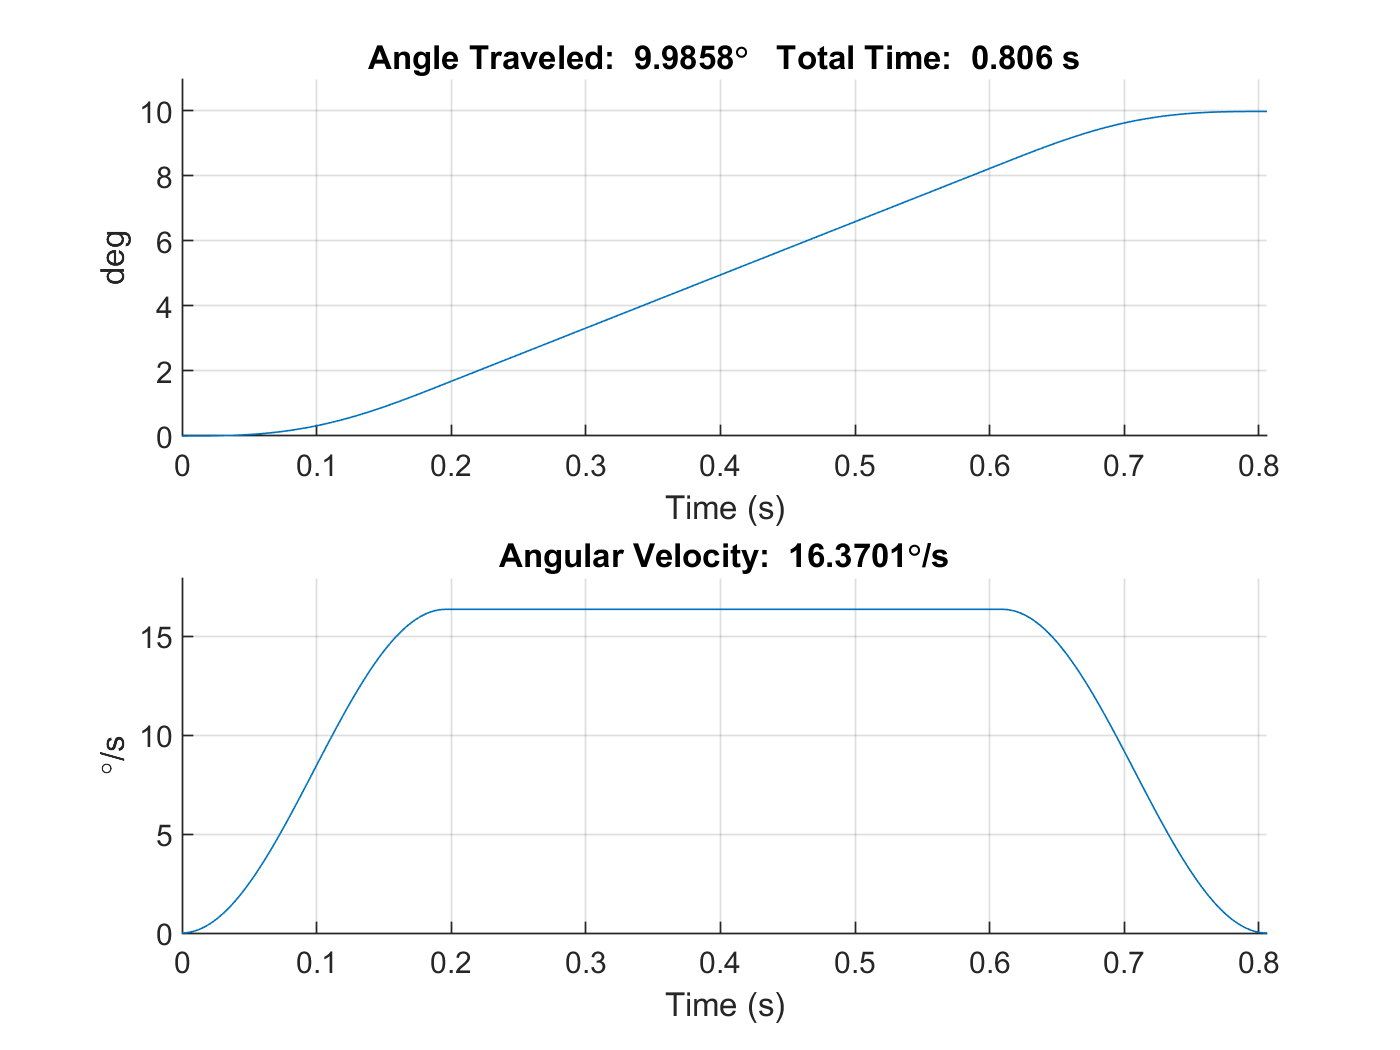

psi_des_deg =10;
psi_des = psi_des_deg * pi/180;

[t_k, psi, w_z] = qbot2_angular_motion_gen(psi_des, 1/1000);
w_z_deg = w_z * 180/pi;
psi_deg = psi * 180/pi;


% Plot Resulting Curve
figure
subplot(2, 1, 1)
hold on
plot(t_k, psi_deg)
title(['Angle Traveled:  ', num2str(psi_deg(end)), '\circ   Total Time:  ', num2str(t_k(end)), ' s'])
xlabel('Time (s)')
ylabel('deg')
xlim([0 t_k(end)])
ylim([0 1.1*psi_deg(end)])
grid on
subplot(2, 1, 2)
hold on
plot(t_k, w_z_deg)
title(['Angular Velocity:  ', num2str(max(w_z_deg)), '\circ/s'])
xlabel('Time (s)')
ylabel('\circ/s')
xlim([0 t_k(end)])
ylim([0 1.1*max(w_z_deg)])
grid on

### Linear Motion Generation Function

function [t_k, r_l, v_l, a_l] = qbot2_linear_motion_gen(r_des, dt)

% Set Traveling Parameters
v_travel = 0.4; % m/s
a_travel = 3/2; % m/s

% Begin Setting t1
t_travel = r_des / v_travel;
t1 = (pi*v_travel) / (2*a_travel);

% Show Down Travel Parameters if t1 is greater than 1/3 the avg time
while (t1 > ((1/3)*t_travel))
    v_travel = v_travel - 0.05;
    a_travel = a_travel - 0.1;
    
    t_travel = r_des / v_travel;
    t1 = (pi*v_travel) / (2*a_travel);
    
    if ((v_travel <= 0) || (a_travel <= 0))
        error('Requested Distance of Travel too small, v_travel or a_travel is negative')
    end
end

% Compute Distance Covered from 0 < t < t1
t = 0 : dt : t1;
a_l = a_travel*sin((pi/t1)*t);

v_l = zeros(1, length(a_l));
r_l = zeros(1, length(a_l));
for k = 2 : length(a_l)
    v_l(k) = a_l(k)*dt + v_l(k-1);
    r_l(k) = v_l(k)*dt + r_l(k-1);
end

r_t1 = r_l(end);

% How long should t1 < t < t2 be?
r_remain = r_des - (2*r_t1);
t2 = r_remain / v_travel;

if (mod(t2, dt) > 0)
    
    new_t2 = 0;
    while (new_t2 < t2)
        new_t2 = new_t2 + dt;
    end
    t2 = new_t2;
end

% Now actually calculate the entire time of travel

% Build Acceleration Cuve

a_l = [a_travel*sin((pi/t1)*t), zeros(1, length(dt:dt:t2-dt)), -a_travel*sin((pi/t1)*t)];

% Integrate to Velocity and Position
t_k = zeros(1, length(a_l));
v_l = zeros(1, length(a_l));
r_l = zeros(1, length(a_l));

for k = 2 : length(a_l)
    t_k(k) = dt * (k - 1);
    v_l(k) = a_l(k)*dt + v_l(k-1);
    r_l(k) = v_l(k)*dt + r_l(k-1);
end


end

### Angular Motion Generation

function [t_k, psi, w_z] = qbot2_angular_motion_gen(psi_des, dt)

% Qbot 2 Parameters
diameter = 0.35;
radius = diameter / 2;
r_des = radius * psi_des;

% Set Traveling Parameters
v_travel = 0.1; % m/s
a_travel = 0.5; % m/s

% Begin Setting t1
t_travel = r_des / v_travel;
t1 = (pi*v_travel) / (2*a_travel);

% Show Down Travel Parameters if t1 is greater than 1/3 the avg time
while (t1 > ((1/3)*t_travel))
    v_travel = v_travel - 0.05;
    a_travel = a_travel - 0.1;
    
    t_travel = r_des / v_travel;
    t1 = (pi*v_travel) / (2*a_travel);
    
    if ((v_travel <= 0) || (a_travel <= 0))
        error('Requested Distance of Travel too small, v_travel or a_travel is negative')
    end
end

% Compute Distance Covered from 0 < t < t1
t = 0 : dt : t1;
a_l = a_travel*sin((pi/t1)*t);

v_l = zeros(1, length(a_l));
r_l = zeros(1, length(a_l));
for k = 2 : length(a_l)
    v_l(k) = a_l(k)*dt + v_l(k-1);
    r_l(k) = v_l(k)*dt + r_l(k-1);
end

r_t1 = r_l(end);

% How long should t1 < t < t2 be?
r_remain = r_des - (2*r_t1);
t2 = r_remain / v_travel;

if (mod(t2, dt) > 0)
    
    new_t2 = 0;
    while (new_t2 < t2)
        new_t2 = new_t2 + dt;
    end
    t2 = new_t2;
end

% Now actually calculate the entire time of travel

% Build Acceleration Cuve

a_l = [a_travel*sin((pi/t1)*t), zeros(1, length(dt:dt:t2-dt)), -a_travel*sin((pi/t1)*t)];

% Integrate to Velocity and Position
t_k = zeros(1, length(a_l));
v_l = zeros(1, length(a_l));
r_l = zeros(1, length(a_l));

for k = 2 : length(a_l)
    t_k(k) = dt * (k - 1);
    v_l(k) = a_l(k)*dt + v_l(k-1);
    r_l(k) = v_l(k)*dt + r_l(k-1);
end

w_z = (psi_des/r_des) .* v_l;
psi = (psi_des/r_des) .* r_l;

end